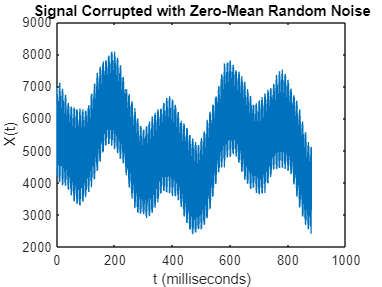

% Create a sample signal
fs = 5681;            % Sampling frequency (Hz)
t = 0:1/fs:1-1/fs;    % Time vector

x = sine5.Current + sine2.Voltage + sine900.Voltage + sine1000.Voltage;


% Compute the FFT
N = length(x);        % Number of samples
X = fft(x);           % Compute FFT

% Compute the frequency axis
f = (0:N-1)*(fs/N);   % Frequency values

% Plot time domain signal
plot(1000*t(1:5000),x(1:5000))
title("Signal Corrupted with Zero-Mean Random Noise")
xlabel("t (milliseconds)")
ylabel("X(t)")

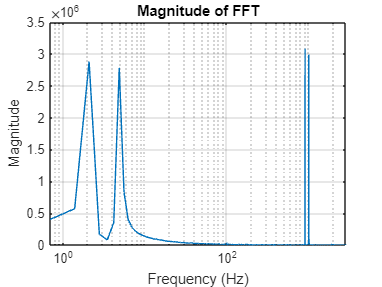


% Plot the magnitude of the FFT
figure;
plot(f, abs(X));
set(gca,'Xscale','log')
title('Magnitude of FFT');
xlabel('Frequency (Hz)');
ylabel('Magnitude');
grid on;

% Zoom in on the plot for better visualization
xlim([0, fs/2]);